% Sinais vindos da simulação
entrada = wdesejada.signals.values;        %% degrau
velocidade = wreal.signals.values;         %% saída
tempo = wreal.time;                        %% tempo

% Ajuste de parâmetros
x0 = [1 1]; %% condição inicial
X = fminsearch(@(x) ErroQuadratico(x, entrada, velocidade, tempo'), x0)

% Parâmetros usados no modelo
Km = X(1);
pm = X(2);

% Função de transferência do modelo do motor
G_motor = tf(Km, [1 pm]) %% função transferência do modelo
ym = lsim(Gp, entrada, tempo); %% saida do modelo para a mesma entrada

%% PROCESSO 
Km = 130;
pm = 5.8;

% G do processo -> isso é o motor, não é isso que a gente controla
Gp = tf(Km, [1 pm]) %% função transferencia do modelo

Gp =
 
    130
  -------
  s + 5.8
 
Continuous-time transfer function.
Model Properties


% Definição de especificações desejadas
tp_desejado = 0.1;  % Tempo de pico desejado, em segundos
Mp_desejado = 25;   % Overshoot máximo permitido, em porcentagem

% Otimização dos parâmetros do controlador
[K_opt, z_opt, p_opt] = otimizaControlador(G_motor, entrada, tempo, tp_desejado, Mp_desejado);

Error using stepinfo (line 61)
The input arguments "Y" and "YFINAL" of the "stepinfo" and "lsiminfo" command must have compatible sizes.

Error in DynamicSystem/stepinfo (line 79)
s = stepinfo(y(1:ns-1,:,:),t(1:ns-1),yf,0,'Ts',abs(sys.Ts),varargin{:});

Error in 

% Definindo o controlador com parâmetros otimizados
Gc = tf([K_opt, K_opt*z_opt], [1, p_opt]);

% Sistema em malha fechada com o controlador
G_malha_fechada = feedback(Gc * G_motor, 1);

% Análise da resposta do sistema em malha fechada
info = stepinfo(G_malha_fechada);
fprintf('Tempo de Pico (tp): %.4f s\n', info.PeakTime);
fprintf('Overshoot (Mp): %.2f %%\n', info.Overshoot);

% Verifica se as especificações são atendidas
if info.PeakTime <= tp_desejado && info.Overshoot <= Mp_desejado
    fprintf('Especificações atendidas para tp e Mp.\n');
else
    fprintf('Especificações NÃO atendidas. Ajuste K, z, ou p.\n');
end

Gp =
 
    130
  -------
  s + 5.8
 
Continuous-time transfer function.
Model Properties


Gc =
 
  10 s + 50
  ---------
   s + 20
 
Continuous-time transfer function.
Model Properties


G_malha_fechada =
 
              0.1 s + 0.5
  ------------------------------------
  0.005 s^3 + 0.16 s^2 + 1.4 s + 2.502
 
Continuous-time transfer function.
Model Properties


Tempo de Pico (tp): 3.0718 s


Overshoot (Mp): 0.00 %


Especificações NÃO atendidas. Ajuste K, z, ou p.


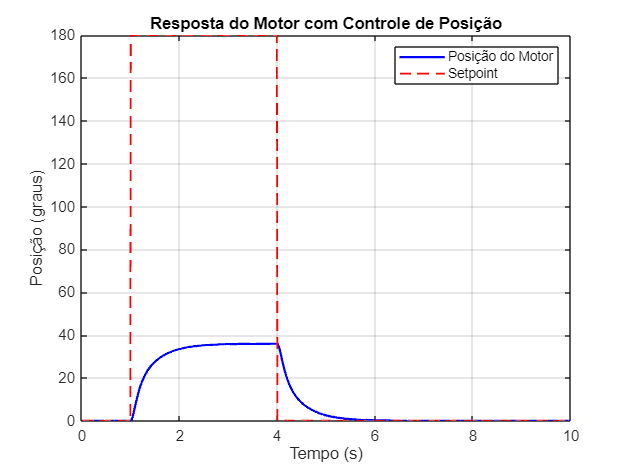

% Simulação do movimento de 180 graus e retorno
t_final = 10; % Tempo total de simulação
t_pause = 3;  % Pausa de 3 segundos após cada movimento

% Define o sinal de entrada para o controle de posição
t = 0:0.01:t_final; 
setpoint = zeros(size(t));
setpoint(t >= 1 & t < 4) = 180; % Movimenta 180 graus e pausa
setpoint(t >= 7) = 0;            % Retorna à posição inicial e pausa

% Simula a resposta do sistema para o setpoint desejado
[y, t_out] = lsim(G_malha_fechada, setpoint, t);

% Plota a resposta do sistema
figure;
plot(t_out, y, 'b', 'LineWidth', 1.5);
hold on;
plot(t, setpoint, 'r--', 'LineWidth', 1.2);
xlabel('Tempo (s)');
ylabel('Posição (graus)');
title('Resposta do Motor com Controle de Posição');
legend('Posição do Motor', 'Setpoint');
grid on;

function [K_opt, z_opt, p_opt] = otimizaControlador(G_motor, entrada, tempo, tp_desejado, Mp_desejado)
    % Argumentos:
    % G_motor -> Função de transferência do motor (já identificado)
    % entrada -> Sinal de entrada para a simulação
    % tempo -> Vetor de tempo correspondente à entrada
    % tp_desejado -> Tempo de pico desejado
    % Mp_desejado -> Overshoot máximo desejado

    % Condições iniciais e limites
    x0 = [1, 1, 1]; % [K, z, p]
    lb = [0, 0, 0]; % Limites inferiores
    ub = [Inf, Inf, Inf]; % Limites superiores

    % Função objetivo
    fun = @(x) custoControlador(x, G_motor, entrada, tempo, tp_desejado, Mp_desejado);

    % Opções do otimizador
    options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');

    % Otimização
    [X_opt, ~] = fmincon(fun, x0, [], [], [], [], lb, ub, [], options);

    % Parâmetros ótimos
    K_opt = X_opt(1);
    z_opt = X_opt(2);
    p_opt = X_opt(3);
end

function custo = custoControlador(x, G_motor, entrada, tempo, tp_desejado, Mp_desejado)
    % Extrai parâmetros
    K = x(1);
    z = x(2);
    p = x(3);

    % Controlador
    Gc = tf([K, K*z], [1, p]);

    % Sistema em malha fechada
    G_malha_fechada = feedback(Gc * G_motor, 1);

    % Resposta ao degrau
    info = stepinfo(G_malha_fechada, tempo, 'SettlingTimeThreshold', 0.02);

    % Cálculo do custo
    custo_tp = (info.PeakTime - tp_desejado)^2;
    custo_Mp = (info.Overshoot - Mp_desejado)^2;

    % Custo total
    custo = custo_tp + custo_Mp;
end

function [Eq] = ErroQuadratico(X,u,y,t)

Km= X(1);
pm = X(2);

%%% Modelo

Gp = tf(Km, [1 pm]);

%%% Saida do modelo

ym = lsim(Gp, u, t);

%%% Erro quadrático

Eq = sum((y-ym).^2); %% cálculo do erro

% plot(t,y,t,ym,"linewidth", 2)

end